# Grades dataset

Clear workspace

clear all; clc; close all;

## Initialize

grades = readtable('grades_km_input.csv');
% class(grades)
% grades.Properties
% head(grades)
size(grades)

ans =    620     4


grades.Properties.VariableNames

ans = 1×4 cell array
    {'Student'}    {'English'}    {'Math'}    {'Science'}


## Stats from data

s = summary(grades)

s = struct with fields:
    Student: [1×1 struct]
    English: [1×1 struct]
       Math: [1×1 struct]
    Science: [1×1 struct]


## Kmeans

X=table2array(grades(:,2:4));

kmax=15;

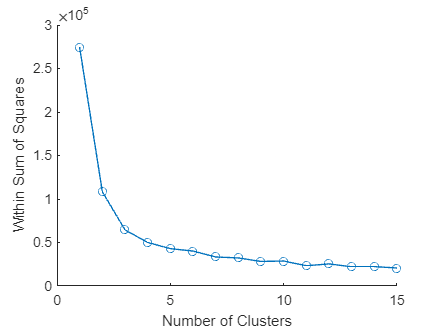

sumt=zeros(kmax,1);
for k=1:kmax
    [idx,C,sumd,D] = kmeans(X,k);
    sumt(k) = sum(sumd);
end

figure(1)
clf
hold on
plot(1:kmax,sumt,'-o')
xlabel('Number of Clusters')
ylabel('Within Sum of Squares')
hold off

### Optimal Kmeans (k=3)

[idx,C,sumd,D] = kmeans(X,3);

g1 = idx==1;
g2 = idx==2;
g3 = idx==3;

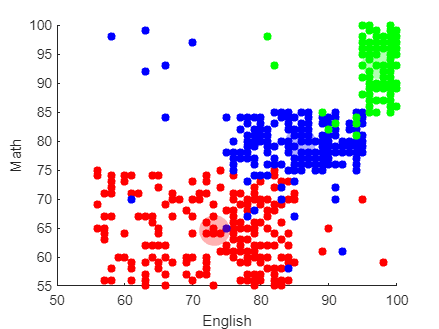

figure(2)
clf
hold on
% Represent cluster elements
scatter(X(g1,1),X(g1,2),'ro',filled='s')
scatter(X(g2,1),X(g2,2),'bo',filled='s')
scatter(X(g3,1),X(g3,2),'go',filled='s')
% Cluster centroids
scatter(C(1,1),C(1,2),500,'ro',filled='s',MarkerFaceAlpha=.3,MarkerEdgeAlpha=.3)
scatter(C(2,1),C(2,2),500,'bo',filled='s',MarkerFaceAlpha=.3,MarkerEdgeAlpha=.3)
scatter(C(3,1),C(3,2),500,'go',filled='s',MarkerFaceAlpha=.3,MarkerEdgeAlpha=.3)
xlabel('English')
ylabel('Math')
hold off

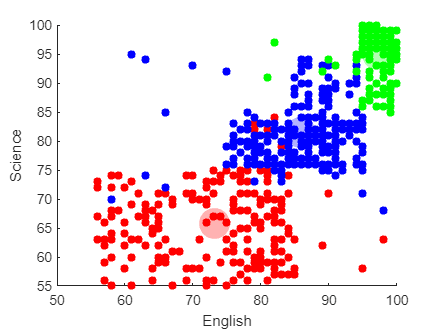

figure(3)
clf
hold on
% Represent cluster elements
scatter(X(g1,1),X(g1,3),'ro',filled='s')
scatter(X(g2,1),X(g2,3),'bo',filled='s')
scatter(X(g3,1),X(g3,3),'go',filled='s')
% Cluster centroids
scatter(C(1,1),C(1,3),500,'ro',filled='s',MarkerFaceAlpha=.3,MarkerEdgeAlpha=.3)
scatter(C(2,1),C(2,3),500,'bo',filled='s',MarkerFaceAlpha=.3,MarkerEdgeAlpha=.3)
scatter(C(3,1),C(3,3),500,'go',filled='s',MarkerFaceAlpha=.3,MarkerEdgeAlpha=.3)
xlabel('English')
ylabel('Science')
hold off

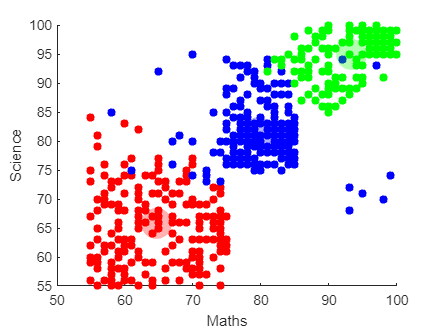

figure(4)
clf
hold on
% Represent cluster elements
scatter(X(g1,2),X(g1,3),'ro',filled='s')
scatter(X(g2,2),X(g2,3),'bo',filled='s')
scatter(X(g3,2),X(g3,3),'go',filled='s')
% Cluster centroids
scatter(C(1,2),C(1,3),500,'ro',filled='s',MarkerFaceAlpha=.3,MarkerEdgeAlpha=.3)
scatter(C(2,2),C(2,3),500,'bo',filled='s',MarkerFaceAlpha=.3,MarkerEdgeAlpha=.3)
scatter(C(3,2),C(3,3),500,'go',filled='s',MarkerFaceAlpha=.3,MarkerEdgeAlpha=.3)
xlabel('Maths')
ylabel('Science')
hold off